# t_wvfOverview

A shift-invariant optical system is characterized by the wavelength-dependent point spread function.  Thus, it is possible to characterize the system by storing the pointspread functions.  Doing so, however, introduces a challenge:  What sample spacing should we use to store the point spreads?  Should they be sampled at 1 micron? or 10 microns?

An alternative to the point spread function, we could store the optical transfer function (OTF), which is the Fourier Transform of the pointspread.  In fact, ISET used this approach for many years.  But it has the same problem:  we must specify the frequency samples of the OTF in advance of any calculation, before we know the spatial sampling of the scene and the optical image.

This problem could be avoided if we have a continuous function to describe the point spread or the OTF. Then we can create the correct function samples at the time of the calculation.  The wavefront aberration representation, using the Zernike polynomials, enables us to efficiently represent the point spread with a continuous function.  And as I explain further below, it offers other advantages by providing intuitive parameters for properties such as defocus and astigmatism. 

For these reasons, we use a wavefront structure to calculate the optical image.  The  Zernike polynomial coefficients of the lens' wavefront aberrations are stored in the struct, along with some metadata that are commonly used in optics and adaptive optics.  The adaptive optics metadata are particularly helpful for the ISETBio calculations that use ISETCam optics.

The wavefront parameters and their current defaults , implemented in wvfCreate, are:

This particular wavefront corresponds to a diffraction-limited lens (ideal lens) with an f-number equal to the human eye (~5.7).  Historical reasons.

The oiCompute function uses the information in the wavefront structure, particularly the Zernike polynomial coefficients, to calculate the point spread function at the proper sampling resolution for the scene and optical image. This tutorial illustrates the properties of the optics that is represented by the wavefront structure and its metadata. We discuss standard properties such as f-number and focal length. We also discuss sample spacing in the psf plane. We show (at the end) how to create a PSF with specific spatial sampling separation.

For those of you particularly interested in ISETBio, the wavefront structure makes it easy to take data from adaptive optics instruments and model the point spread functions of the human eye.  Tutorials about the human eye are in the ISETBio repository.

**See also - **

         wvfCompute, wvfGet, wvfSet, wvf2oi, wvf2optics, wvfPlot, wvfSummarize, wvf*

## An image of the pupil plane

The wavefront aberrations are specified in the pupil plane.  Typically, we specify the wavefront aberrations with respect to the measured pupil diameter.  This measured pupil might be 8 mm, say for a human eye with the pupil opened up wide.  The Zernike polynomial software returns polynomials over a disk, and the measured pupil diameter tells us how large the disk is. 

We sample the values of the wavefront aberrations in the pupil plane over a reference field size. By default this size is 16.212 mm (I don't know why this value).  It has to be larger than the measured pupil diameter for the Fourier transforms to work out later.

The number of samples specifies the discretization over this plane.  The field size and number of samples are always square.

Finally, we can perform a calculation over a pupil that is smaller than the measured pupil size (calc pupil diameter).  It can not be larger because, well, we don't know the aberrations over that size.

The functions wvfCompute() which calls wvfComputePupilFunction() and wvfComputePSF() read these parameters to produce the OTF and the PSF of the optics.

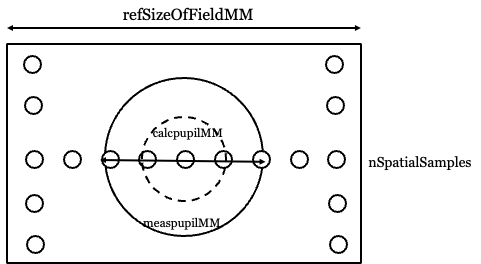

## Image plane

The wvf represents the number of microns per degree explicitly.  This can be used to infer the focal length.  The focal length and the calculated pupil diameter can be used to infer the f number or the numerical aperture (NYI).

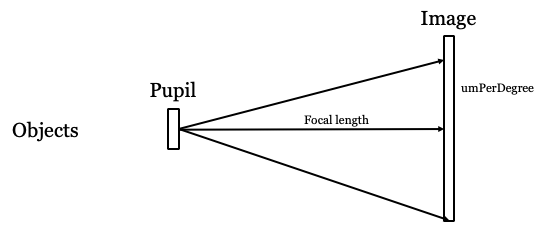

## The default wavefront

There are enough parameters with enough units that we felt the need to write a function to summarize them and their units.

wvf = wvfCreate;
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


## Number of spatial samples

Changing this parameter changes the size of the PSF support but not the PSF spacing. It changes the OTF spacing, but not the highest frequency for the OTF support.

wvf = wvfCreate;
wvf = wvfSet(wvf,'npixels',101);
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 101
ref pupil plane	 16.212000	 mm
ref pupil dx	 160.514851	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 17.148651	 cyc/mm
Max PSF support	 29.156813	 um
PSF dx		 0.583136	 um
-------------------


wvf = wvfSet(wvf,'npixels',801);
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 801
ref pupil plane	 16.212000	 mm
ref pupil dx	 20.239700	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 2.143581	 cyc/mm
Max PSF support	 233.254502	 um
PSF dx		 0.583136	 um
-------------------


## Focal length 

Changing the focal length is equivalent to changing um per degree.  It also changes the f number.

The spacing and support of the PSF and OTF both change (see image plane figure above to get an intuition of why). When the focal length is small, the pixels in the pupil plane map into a high spatial density in the image plane.  Thus, the peak spatial frequency is also much higher.

wvf = wvfCreate;
wvf = wvfSet(wvf,'focal length',4,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 1.333333
f length	 4.000000	 mm
um per deg	 69.814942	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 3684.451923	 cyc/mm
OTF df		 36.844519	 cyc/mm
Max PSF support	 13.570539	 um
PSF dx		 0.135705	 um
-------------------


wvf = wvfSet(wvf,'focal length',40,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 13.333333
f length	 40.000000	 mm
um per deg	 698.149423	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 368.445192	 cyc/mm
OTF df		 3.684452	 cyc/mm
Max PSF support	 135.705394	 um
PSF dx		 1.357054	 um
-------------------


The values of the PSF change.  In this case, however, they seem similar in the graph but notice that the sample spacing has changed dramatically between the two plots.  One is supported over only a litle more than 10 microns, and the other is supported over more than 100 um.

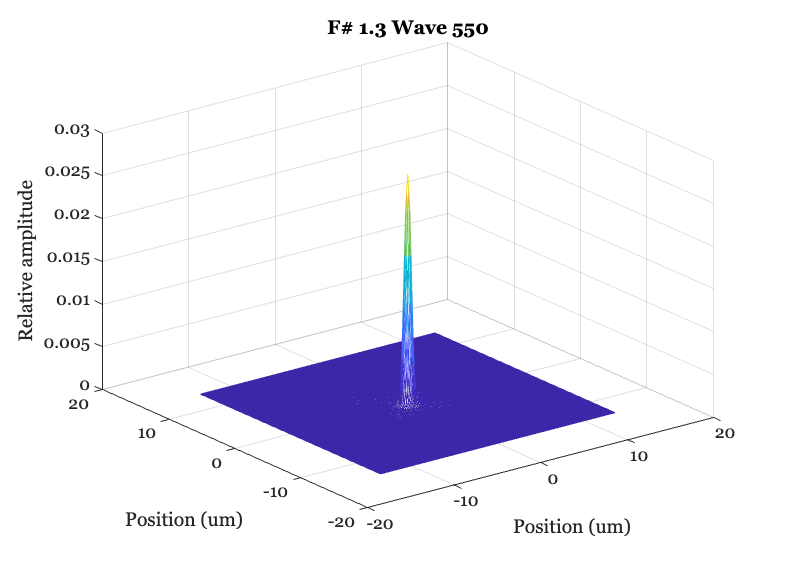

wvf = wvfSet(wvf,'focal length',4,'mm');
wvf = wvfCompute(wvf); 
wvfPlot(wvf,'psf','unit','um','plot range',15);

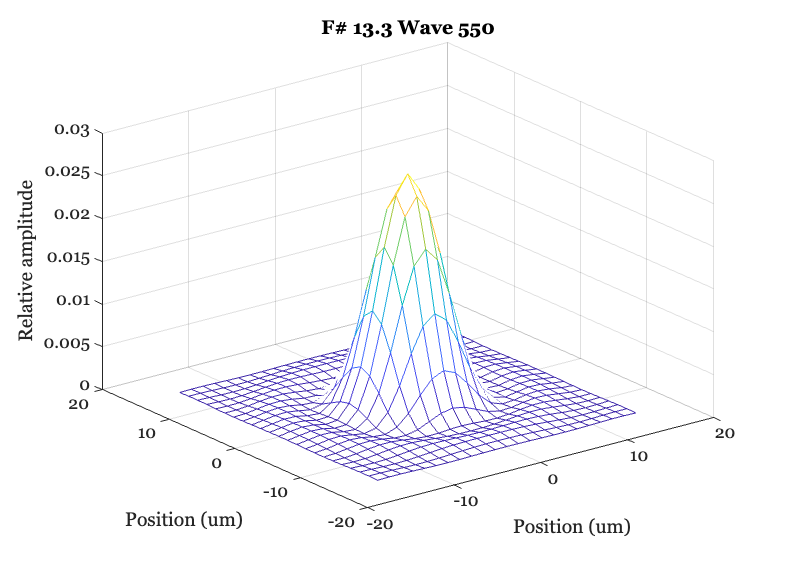

wvf = wvfSet(wvf,'focal length',40,'mm');
wvf = wvfCompute(wvf); 
wvfPlot(wvf,'psf','unit','um','plot range',15);

## Calc pupil diameter

This cal pupil is used when we perform the actual computation.  Changing its value does not change the PSF and OTF sampling parameters

wvf = wvfCreate;
wvf = wvfSet(wvf,'calc pupil diameter',1,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 17.188300
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 1.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


This is the diffraction limited PSF for a 1 mm pupil, which is an F# of 17.2

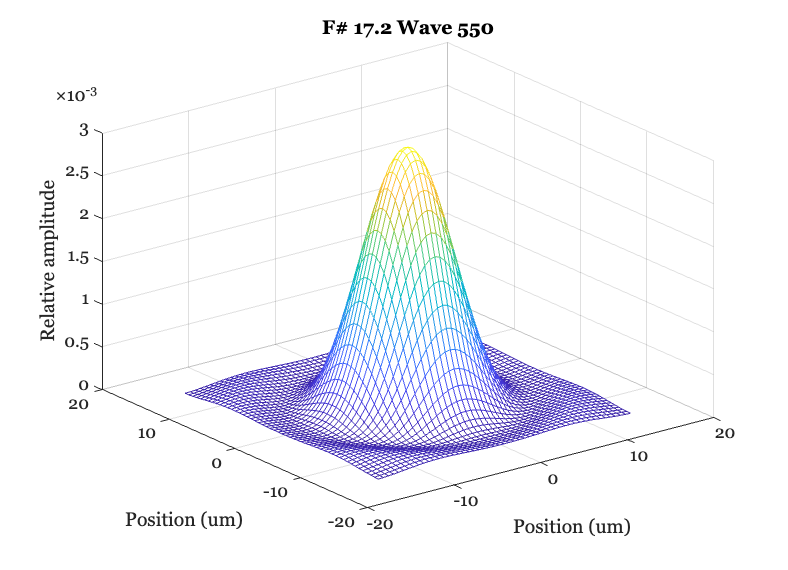

wvf = wvfCompute(wvf); 
wvfPlot(wvf,'psf','unit','um','plot range',15);

Notice that increasing the size of the pupil diameter changes the F# to 2.9.  It does **not** change the sample values of the OTF or PSF.  The zCoeffs, zDiameter and OTF/PSF parameters are unchanged.  But the values of the PSF (and OTF) measured at those sample values does change. As the pupil opens up, the diffraction limted PSF gets mch smaller.  Notice that the PSF sample positions is unchanged.

wvf = wvfSet(wvf,'calc pupil diameter',6,'mm');
wvf = wvfCompute(wvf);
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 2.864717
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 6.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


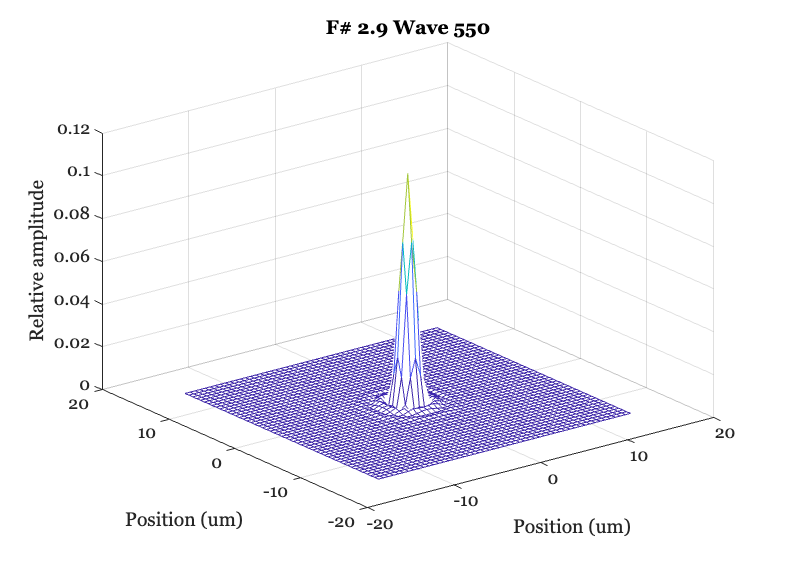

wvfPlot(wvf,'psf','unit','um','plot range',15);

## Change the measured pupil specification

For a diffraction limited case, when the zcoefs are simply 0, changing the measured pupil is irrelevant.  If we made it bigger or smaller, we would still be diffraction limited and only the size of the calc pupil matters.

wvf = wvfCreate;
wvf = wvfSet(wvf,'measured pupil diameter',1,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 1.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


wvf = wvfSet(wvf,'measured pupil diameter',6,'mm');
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 6.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


You can see that the PSF is unchanged because the calc pupil diameter is unchanged.

wvf = wvfSet(wvf,'measured pupil diameter',1,'mm');
wvf = wvfSet(wvf,'calc pupil diameter',1,'mm');
wvf = wvfCompute(wvf);
wvfPlot(wvf,'psf','unit','um','plot range',15);

wvf = wvfSet(wvf,'measured pupil diameter',6,'mm');
wvf = wvfSet(wvf,'calc pupil diameter',1,'mm');
wvf = wvfCompute(wvf);
wvfPlot(wvf,'psf','unit','um','plot range',15);

## Match a target OI sample spacing

This next section analyzes how we control the PSF sample spacing.  We often want to do this so we can create an OI image that matches the spatial sampling of the sensor pixels.  The key is to adjust the field size, or a combination of the reference field size and the number of spatial samples in the field.  (I think).

lambdaMM = 550e-6;
fnumber = 4;
focallengthMM = 4;
nPixels = 1024;

wvf = wvfSet(wvf, 'focal length', focallengthMM, 'mm');
wvf = wvfSet(wvf, 'calc pupil diameter', focallengthMM/fnumber);
wvf = wvfSet(wvf, 'spatial samples', nPixels);

% this is what we are trying to match
psf_spacingMM = 1e-3; 

% compute the pupil sample spacing that matches this PSF sample
% spacing in the image plane.
pupil_spacingMM = lambdaMM * focallengthMM / (psf_spacingMM * nPixels);

wvf = wvfSet(wvf,'field size mm', pupil_spacingMM * nPixels);

The PSF spacing is about 1 micron after these sets.

wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 4.000000
f length	 4.000000	 mm
um per deg	 69.814942	 um
calc pupil diam	 1.000000	 mm

Reference
------
n samples	 1024
ref pupil plane	 2.200000	 mm
ref pupil dx	 2.148438	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 6.000000	 mm
Max OTF freq	 499.010770	 cyc/mm
OTF df		 0.976538	 cyc/mm
Max PSF support	 511.012972	 um
PSF dx		 1.000025	 um
-------------------


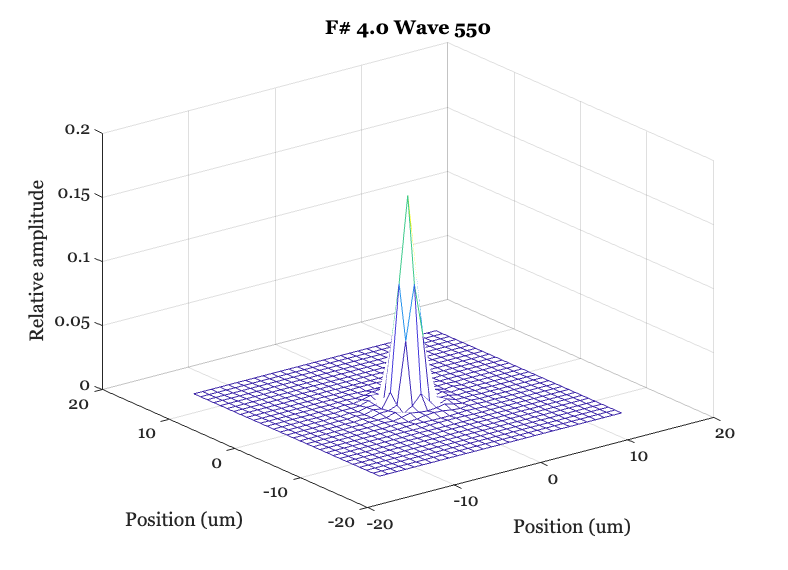

wvf = wvfCompute(wvf);
wvfPlot(wvf,'psf','unit','um','plot range',15);

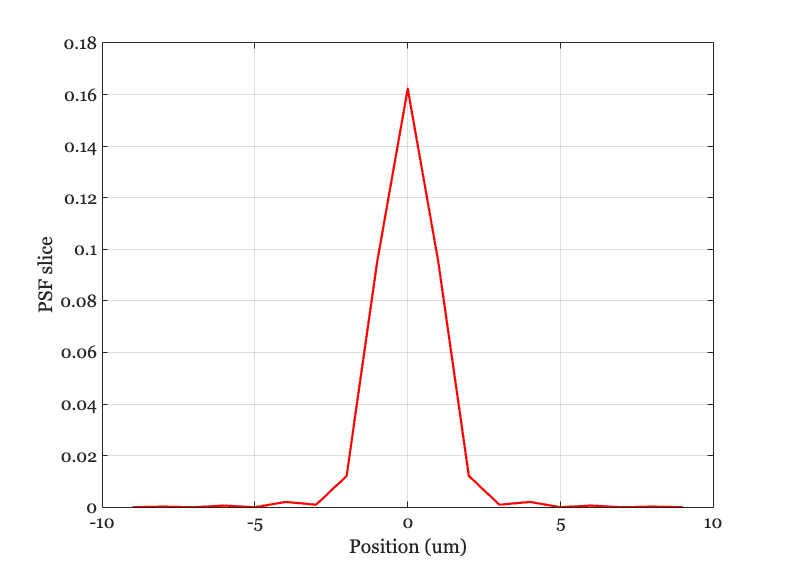


wvfPlot(wvf, '1d psf space', 'unit', 'um','plot range',10);

Notice that these settings made the pupil plane just 2.2 mm.  This value can be smaller than many pupil diameter cases.  That should be avoided.

Here we set the psf spacing to 2 microns. The PSF is the same spread, except coarsely sampled.

psf_spacingMM = 2e-3; 
pupil_spacingMM = lambdaMM * focallengthMM / (psf_spacingMM * nPixels);
wvf = wvfSet(wvf,'field size mm', pupil_spacingMM * nPixels);
wvfSummarize(wvf);


wavefront struct name: default
-------------------
f number	 4.000000
f length	 4.000000	 mm
um per deg	 69.814942	 um
calc pupil diam	 1.000000	 mm

Reference
------
n samples	 1024
ref pupil plane	 1.100000	 mm
ref pupil dx	 1.074219	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 6.000000	 mm
Max OTF freq	 249.505385	 cyc/mm
OTF df		 0.488269	 cyc/mm
Max PSF support	 1022.025944	 um
PSF dx		 2.000051	 um
-------------------


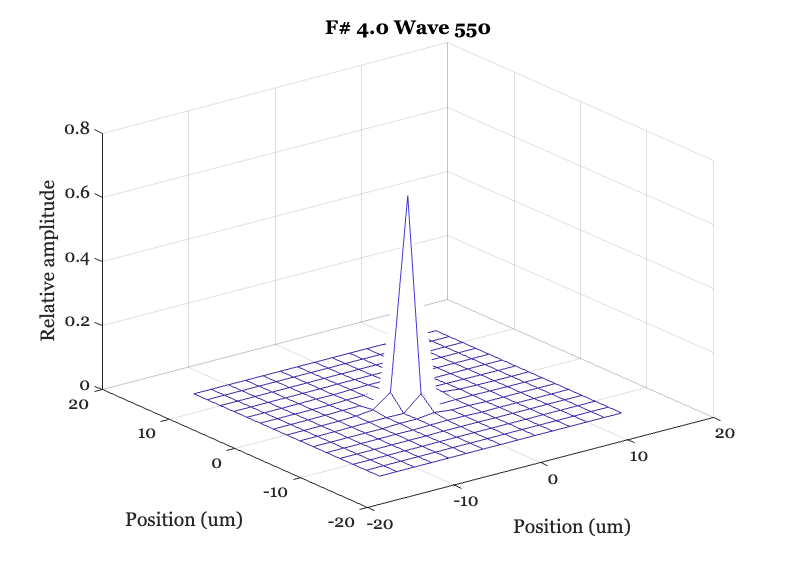

wvf = wvfCompute(wvf);
wvfPlot(wvf,'psf','unit','um','plot range',15);

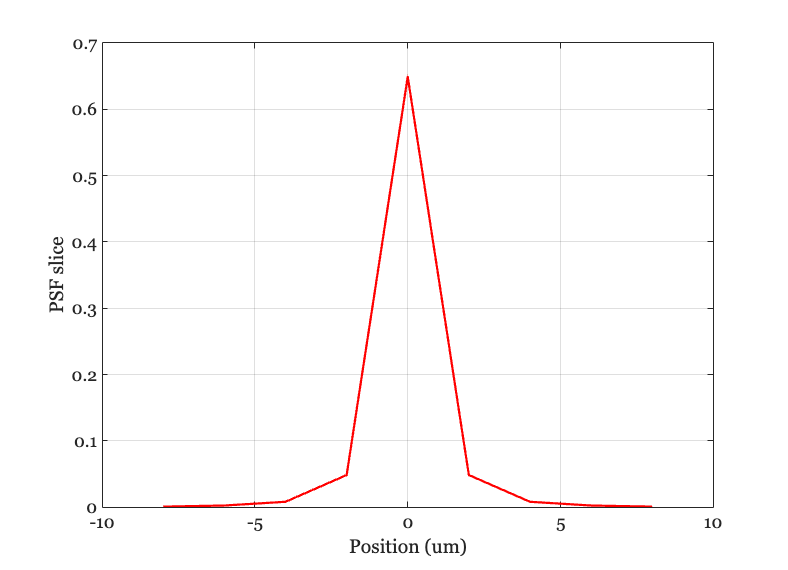

wvfPlot(wvf, '1d psf space', 'unit', 'um','plot range',10);

## Other parameters 

The Stiles-Crawford effect (SCE) and some other parameters are not discussed here.  They will be described in the scripts and other calculations.

- sce

- measObserverAcommodationDiopters - 0

- constantSampleIntervalDomain - 'psf'

- conePsfInfo